# FitTestTemplate

This script is a template for a script to test nonlinear regression. Save it as YourFirstNameYourLastName.mlx and then edit it to fill in missing steps.

Author: Your First Name Your Last Name

Create some independent variable values dependent variable values with nonlinear dependence and one parameter (omega).

t=[0:.1:4*pi]';
N=length(t);
omega=1;
A=2;
y=A*sin(omega*t);

Add random values to dependent variable values using [randn](https://www.mathworks.com/help/matlab/ref/randn.html). The random values are normally distributed with 0 mean and unit variance  Be careful to create a column vector.

%

Make column vector `yerr` of uniform unit estimated errors using [ones](https://www.mathworks.com/help/matlab/ref/ones.html).

%

Plot `y` versus `t` with errors `yerr` using [errorbar](https://www.mathworks.com/help/matlab/ref/errorbar.html).

%

Create model function

modelfun= @(b,t)(b(1)*sin(b(2)*t))

modelfun = function_handle with value:
    @(b,t)(b(1)*sin(b(2)*t))


Initialize parameter estimates.

%b0= ;

Set options

opts = statset('nlinfit');

Call nlinfit.

%[beta,R,J,CovB,MSE,ErrorModelInfo] = ...
%    nlinfit(t,y,modelfun,b0);

List results for parameters.

%

beta =        2.0333
      0.99641


Compute standard errors on parameters

sqrt(diag(CovB))

ans =       0.12393
    0.0084543


Superpose fit on plot with labels and legend.

%hold on
%yfit=
%plot(t,yfit)

Label, entitle, and legend the plot.

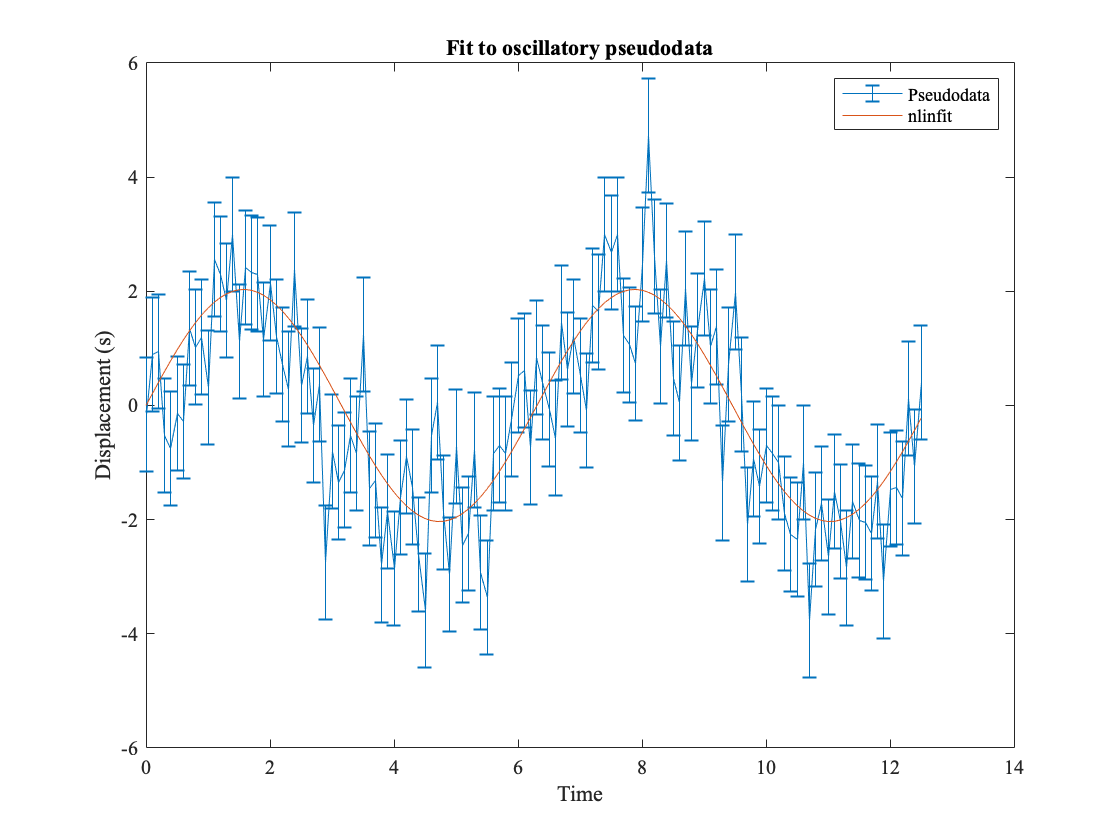

xlabel('Time');ylabel('Displacement (s)')
legend('Pseudodata','nlinfit')
title('Fit to oscillatory pseudodata')